# Modeling Overhead Gantry Crane

We will derive the equations of motion for an overhead gantry crane system. We simplify the gantry cane system as just a payload (pendulum) on a movable support, as illustrated in the diagram below:

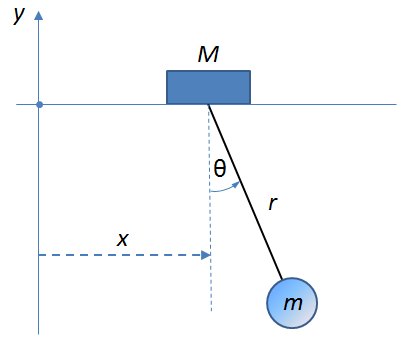

Where:

- r = length of pendulum

- m = mass of bob

- M = mass of the movable support

- θ = angle of pendulum with respect to vertical; measure positive counterclockwise

## Euler-Lagrange equations of motion

## 
$$\frac{d}{dt}\frac{\partial L}{\partial \dot{q_k}} - \frac{\partial L}{\partial q_k} = \tau_k; \qquad k=1 \ldots n$$


where  *n* is the DOF of the system, { *q*  *(1)*  *... q*  *(n)* } is a set of generalized coordinates, { *τ*  *(1)*  *...*  *τ*  *(n)* } is the set of generalized forces associated with those coordinates,and the Lagrangian:  *L* =  *T*  *-*  *V,* is defined as the difference between the kinetic and potential energy of the  *n-* DOF system.

**Note** : For system, we will choose  *q = {X,*  *θ*  *}* 

## Setting up theta and etheta 

syms theta(t) 
th = theta(t)

$$th = \theta \left(t\right)$$

## Defining normalized unit vectors for X and *θ* (perpendicular to tangent)

ei = [sym(1); sym(0)]

$$ei = \left(\begin{array}{c} 1\\ 0 \end{array}\right)$$

etheta = [cos(th);sin(th)]

$$etheta = \left(\begin{array}{c} \cos\left(\theta \left(t\right)\right)\\ \sin\left(\theta \left(t\right)\right) \end{array}\right)$$

## Defining veloctites for the two masses (M and m) in order to calculate T (Kinetic Energy)

syms r X(t)
vM = diff(X) * ei

$$vM(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}X\left(t\right)\\ 0 \end{array}\right)$$

vm = diff(X) * ei + r * diff(theta) * etheta

$$vm(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}X\left(t\right)+r\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ r\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

## Defining Kinetic Energy and Potential Energy:

syms M g m
KE = simplify(1/2 * M * transpose(vM) * vM + 1/2 * m * transpose(vm) * vm)

$$KE(t) = \frac{M\,{\left(\frac{\partial }{\partial t}X\left(t\right)\right)}^{2}}{2}+\frac{m\,{\left(\frac{\partial }{\partial t}X\left(t\right)\right)}^{2}}{2}+\frac{m\,r^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+m\,r\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}X\left(t\right)$$

PE = -(m * g * r * cos(theta))

$$PE(t) = -g\,m\,r\,\cos\left(\theta \left(t\right)\right)$$

## Calculating the Lagrangian function (T - V or KE - PE)

L = simplify(KE + PE * -1)

$$L(t) = \frac{M\,{\left(\frac{\partial }{\partial t}X\left(t\right)\right)}^{2}}{2}+\frac{m\,{\left(\frac{\partial }{\partial t}X\left(t\right)\right)}^{2}}{2}+\frac{m\,r^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+g\,m\,r\,\cos\left(\theta \left(t\right)\right)+m\,r\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}X\left(t\right)$$

## Calculating Partial Derivatives of the Lagrangian:

To facilitate obtaining the partial derivatives of the Lagrangian, we will substitute our states  *{X(t),X'(t),*  *θ*  *(t),*  *θ*  *'(t)}* for a set of temporary variables *{q1*  *,q1p*  *, q2*  *,q2p*  *}* 

syms q1 q_1_p q2 q_2_p
L = subs(L, {X(t), diff(X), theta, diff(theta)} , [q1, q_1_p, q2, q_2_p])

$$L(t) = \frac{M\,{q_{1,p}}^{2}}{2}+\frac{m\,{q_{1,p}}^{2}}{2}+\frac{m\,{q_{2,p}}^{2}\,r^{2}}{2}+g\,m\,r\,\cos\left(q_{2}\right)+m\,q_{1,p}\,q_{2,p}\,r\,\cos\left(q_{2}\right)$$

## Partial derivative of the Lagrangian with respect to q2p = θ'(t) and q2 = θ(t) and resubsitution

dLdq2p = diff(L, q_2_p)

$$dLdq2p(t) = m\,q_{2,p}\,r^{2}+m\,q_{1,p}\,\cos\left(q_{2}\right)\,r$$

dLdq2p = subs(dLdq2p, [q1, q_1_p, q2, q_2_p], [X(t), diff(X), theta, diff(theta)])

$$dLdq2p(t) = m\,r^{2}\,\frac{\partial }{\partial t}\theta \left(t\right)+m\,\cos\left(\theta \left(t\right)\right)\,r\,\frac{\partial }{\partial t}X\left(t\right)$$

dLdq2 = diff(L, q2)

$$dLdq2(t) = -g\,m\,r\,\sin\left(q_{2}\right)-m\,q_{1,p}\,q_{2,p}\,r\,\sin\left(q_{2}\right)$$

dLdq2 = subs(dLdq2, [q1, q_1_p, q2, q_2_p], [X(t), diff(X), theta, diff(theta)])

$$dLdq2(t) = -m\,r\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}X\left(t\right)-g\,m\,r\,\sin\left(\theta \left(t\right)\right)$$

## Equations of motion

The dynamics of the  *n* -DOF system will be described by a set of  *n* coupled second order differential equations. We convert our second order order equations to a set of first ordered equations to solve them numerically. 

Euler-Lagrange equation corresponding to coordinate  *θ* 

eqn2 = diff(dLdq2p, t) - dLdq2 == sym(0)

$$eqn2(t) = m\,r^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+m\,\cos\left(\theta \left(t\right)\right)\,r\,\frac{\partial^{2}}{\partial t^{2}}X\left(t\right)+g\,m\,\sin\left(\theta \left(t\right)\right)\,r=0$$

Using equation above, derive equation for θ''(t) 

syms DT2;
dt2 = diff(theta,2);

eq2_T = solve(subs(eqn2, dt2, DT2), DT2)

$$eq2\_T = -\frac{\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}X\left(t\right)+g\,\sin\left(\theta \left(t\right)\right)}{r}$$

syms accel(t) y1 y2
MLoutput = subs(eq2_T, {th, diff(th), diff(X, 2)}, {y1, y2, accel(t)})

$$MLoutput = -\frac{\mathrm{accel}\left(t\right)\,\cos\left(y_{1}\right)+g\,\sin\left(y_{1}\right)}{r}$$

f = matlabFunction(MLoutput,'file','odeEqn');

Undefined function or variable 'swingeq'.


*Copyright 2017 The MathWorks, Inc.*